clear all;
close all;
clc;

addpath(genpath('C:\Users\PC\OneDrive\Documentos\MATLAB\cobratoolbox'))

% Inicializar COBRA Toolbox
initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.45.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.


 > TranslateSBML is installed and working properly.
 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [*---] GUROBI_PATH: C:\gurobi1001\win64\matlab
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ...

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Original LP has 1 row, 2 columns, 1 non-zero
Objective value = 0
OPTIMAL SOLUTION FOUND BY LP PRESOLVER

 > [glpk] Primal optimality condition in solveCobraLP satisfied.Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle 

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek    


% Cambiar el solver a GLPK
changeCobraSolver('glpk', 'all');

 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2024a.
 > changeCobraSolver: Solver for LP problems has been set to glpk.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2024a.
 > changeCobraSolver: Solver for MILP problems has been set to glpk.
 > changeCobraSolver: Solver glpk not supported for problems of type EP. No solver set for this problemtype 
 > changeCobraSolver: Solver glpk not supported for problems of type MIQP. No solver set for this problemtype 
 > changeCobraSolver: Solver glpk not supported for problems of type NLP. No solver set for this problemtype 
 > changeCobraSolver: Solver glpk not supported for problems of type QP. Currently used: pdco 


## Define paths and load necessary data

cd('C:/Users/PC/OneDrive/Documentos/Systems_Biology_master/Internship/Internship/Thresholding/LocalT2');
currentFolder = pwd;
cd('C:/Users/PC/OneDrive/Documentos/Systems_Biology_master/Internship/Internship/Data');
data = readtable("data_TPM.xlsx");
h_k_g = readtable('NM2ENSG.xlsx');
housekeep_react_enz_eis = load('housekeep_react_enz_eis.mat');
housekeep_react_enz_eis = housekeep_react_enz_eis.hk_reactions_unique;
new_HKG_list = readtable('ENS_ID_HKG.xlsx');
new_HKG_list_enz = load('housekeep_react_enz_new.mat');
new_HKG_list_enz = new_HKG_list_enz.hk_reactions_unique;
test_HKG = readtable('journal.pcbi.1010295.s014.xlsx', 'Sheet','Human');
test_HKG = table2cell(test_HKG);
HKG_list_enz_test = load('housekeep_react_enz_test.mat');
HKG_list_enz_test = HKG_list_enz_test.hk_reactions_unique;
model = load('SysBio_COBRA_v1.17_consensus.mat'); % Human1 metabolic model
model = model.myModel;
model_Alicia = load('SysBio_COBRA_v1.17_consensus1.mat');
model_Alicia = model_Alicia.myModel;
model_p = load('model.mat');
model_p = model_p.model;
model_genes_p = model_p.genes; % ENSEMBL_IDs of the genes in the model
model_genes = model.genes;
cd(currentFolder);

## Preprocess data

Ensembl_id = data(:, 1);
NamesSample = data.Properties.VariableNames(2:end); 
data_to_log = table2array(data(:, 2:end));
logged_data = log10(data_to_log + 2); % Normalize the data (+1 to avoid having 0 values) 

% Create the new table with normalized data
log_data = [Ensembl_id, array2table(logged_data)]; 
log_data.Properties.VariableNames(2:end) = NamesSample; 
log_data.Properties.VariableNames{1} = 'gene'; 


## Extract metabolic gene expression from both pruned and unpruned models

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% UNPRUNED MODEL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
geneExpressionMatrix = [];
for i = 1:width(NamesSample)
    log_data.value = log_data{:, i + 1};
    [geneList, geneExpression] = findUsedGenesLevels(model, log_data); 
    geneExpressionMatrix = [geneExpressionMatrix, geneExpression'];
    log_data.value = [];
end

% Convert results into a table
metabolic_genes = array2table(geneExpressionMatrix, 'RowNames', geneList, 'VariableNames', NamesSample);
metabolic_genes = rmmissing(metabolic_genes, 'MinNumMissing', size(metabolic_genes, 2)); 
save('metabolic_genes.mat', 'metabolic_genes')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% PRUNED MODEL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
geneExpressionMatrix_P = [];
for i = 1:width(NamesSample)
    log_data.value = log_data{:, i + 1}; 
    [geneList, geneExpression] = findUsedGenesLevels(model_p, log_data); 
    geneExpressionMatrix_P = [geneExpressionMatrix_P, geneExpression'];
    log_data.value = [];
end

% Convert results into a table
metabolic_genes_P = array2table(geneExpressionMatrix_P, 'RowNames', geneList, 'VariableNames', NamesSample);
metabolic_genes_P = rmmissing(metabolic_genes_P, 'MinNumMissing', size(metabolic_genes_P, 2)); 
save('metabolic_genes_P.mat', 'metabolic_genes_P')

## Housekeeping reactions

hkg_met = model_p.genes(ismember(model_p.genes, h_k_g.converted_alias));
results_HKReact = findRxnsFromGenes_Alicia(model_p, hkg_met);

Input: string of single gene or cell array of multiple genes



fields = fieldnames(results_HKReact);
housekeep_react = {};
for i = 1:length(fields)
    field = fields{i};
    cellArray = results_HKReact.(field);
    for j = 1:size(cellArray, 1)
        firstcol = cellArray{j, 1};
        housekeep_react{end+1, 1} = firstcol;
    end
end
housekeep_react_unique = unique(housekeep_react);
disp(housekeep_react_unique);

    {'MAR00001'}
    {'MAR00003'}
    {'MAR00005'}
    {'MAR00006'}
    {'MAR00010'}
    {'MAR00067'}
    {'MAR00080'}
    {'MAR00091'}
    {'MAR00113'}
    {'MAR00114'}
    {'MAR00115'}
    {'MAR00117'}
    {'MAR00118'}
    {'MAR00121'}
    {'MAR00122'}
    {'MAR00129'}
    {'MAR00133'}
    {'MAR00153'}
    {'MAR00154'}
    {'MAR00155'}
    {'MAR00158'}
    {'MAR00164'}
    {'MAR00167'}
    {'MAR00170'}
    {'MAR00173'}
    {'MAR00176'}
    {'MAR00179'}
    {'MAR00183'}
    {'MAR00187'}
    {'MAR00188'}
    {'MAR00190'}
    {'MAR00191'}
    {'MAR00192'}
    {'MAR00195'}
    {'MAR00196'}
    {'MAR00199'}
    {'MAR00200'}
    {'MAR00203'}
    {'MAR00204'}
    {'MAR00208'}
    {'MAR00209'}
    {'MAR00212'}
    {'MAR00213'}
    {'MAR00216'}
    {'MAR00217'}
    {'MAR00225'}
    {'MAR00226'}
    {'MAR00232'}
    {'MAR00233'}
    {'MAR00236'}
    {'MAR00237'}
    {'MAR00240'}
    {'MAR00241'}
    {'MAR00244'}
    {'MAR00245'}
    {'MAR00248'}
    {'MAR00249'}
    {'MAR00254'}
    {'MAR00255

## Start plotting and parallel processing

delete(gcp('nocreate'));
parpool('local');

Starting parallel pool (parpool) using the 'Processes' profile ...
17-Jun-2024 14:01:34: Job Queued. Waiting for parallel pool job with ID 1 to start ...
17-Jun-2024 14:02:35: Job Queued. Waiting for parallel pool job with ID 1 to start ...
17-Jun-2024 14:03:35: Job Queued. Waiting for parallel pool job with ID 1 to start ...
Connected to parallel pool with 4 workers.



numColumns = size(metabolic_genes, 2);
numIterations = 11; % From upper_p = 100 to 50, decrementing by 5 each time

% Preallocate matrices for results
HK_CG_G_all = zeros(numColumns, numIterations);
HK_CR_R_all = zeros(numColumns, numIterations);
HK_CG_G_recall_values_all = zeros(numColumns, numIterations);
HK_CR_R_recall_values_all = zeros(numColumns, numIterations);

mean_HK_CG_G_all = zeros(1, numIterations);
std_HK_CG_G_all = zeros(1, numIterations);
mean_HK_CG_G_recall_values_all = zeros(1, numIterations);
std_HK_CG_G_recall_values_all = zeros(1, numIterations);
mean_HK_CR_R_all = zeros(1, numIterations);
std_HK_CR_R_all = zeros(1, numIterations);
mean_HK_CR_R_recall_values_all = zeros(1, numIterations);
std_HK_CR_R_recall_values_all = zeros(1, numIterations);

gene_names_P = metabolic_genes_P.Properties.RowNames;

% Crear una estructura base para expressionData fuera del bucle
expressionData.gene = gene_names_P;
expressionData.value = [];

index = 1; % Inicializamos el índice antes del loop
for upper_p = 100:-5:50
    lower_p = 100 - upper_p;
    disp(['upper_p = ', num2str(upper_p), ', lower_p = ', num2str(lower_p)]);
    
    [adjusted_matrix, IMR90_Y2_norm] = localT2_function(metabolic_genes_P, metabolic_genes, lower_p, upper_p);
    
    % Inicializamos matrices para almacenar los resultados de las 48 columnas
    HK_CG_G_all_temp = zeros(1, 48);
    HK_CG_G_recall_values_all_temp = zeros(1, 48);
    HK_CR_R_all_temp = zeros(1, 48);
    HK_CR_R_recall_values_all_temp = zeros(1, 48);
    
    % Convert expressionData.gene to a sliced variable
    expressionDataGene = expressionData.gene;
    
    parfor col = 1:48
        % Calculamos los valores de IMR90_Y2_CG y HK_CG_G_all
        IMR90_Y2_CG = gene_names_P(IMR90_Y2_norm(:, col) >= 1);
        HK_CG_G_all_temp(col) = (length(IMR90_Y2_CG) / length(IMR90_Y2_norm(:, col))) * 100;
        HK_CG_G_rec = hkg_met(ismember(hkg_met, IMR90_Y2_CG));
        HK_CG_G_recall = (length(HK_CG_G_rec) / length(hkg_met)) * 100;
        HK_CG_G_recall_values_all_temp(col) = HK_CG_G_recall;
        
        % Preparar los datos de expresión
        expressionDataSample = struct();
        expressionDataSample.gene = expressionDataGene; % Use the sliced variable here
        expressionDataSample.value = IMR90_Y2_norm(:, col);
        
        IMR90_Y2_normCR = mapExpressionToReactions(model_p, expressionDataSample, false);
        
        IMR90_Y2_CR = model_p.rxns(IMR90_Y2_normCR >= 1);
        HK_CR_R_all_temp(col) = (length(IMR90_Y2_CR) / length(model_p.rxns)) * 100;
        HK_CR_R_rec = housekeep_react_unique(ismember(housekeep_react_unique, IMR90_Y2_CR));
        HK_CR_R_recall = (length(HK_CR_R_rec) / length(housekeep_react_unique)) * 100;
        HK_CR_R_recall_values_all_temp(col) = HK_CR_R_recall;
    end
    
    % Calculamos la media y desviación estándar para cada iteración
    mean_HK_CG_G_all(index) = mean(HK_CG_G_all_temp);
    std_HK_CG_G_all(index) = std(HK_CG_G_all_temp);
    mean_HK_CG_G_recall_values_all(index) = mean(HK_CG_G_recall_values_all_temp);
    std_HK_CG_G_recall_values_all(index) = std(HK_CG_G_recall_values_all_temp);
    mean_HK_CR_R_all(index) = mean(HK_CR_R_all_temp);
    std_HK_CR_R_all(index) = std(HK_CR_R_all_temp);
    mean_HK_CR_R_recall_values_all(index) = mean(HK_CR_R_recall_values_all_temp);
    std_HK_CR_R_recall_values_all(index) = std(HK_CR_R_recall_values_all_temp);
    
    disp(['Mean HK_CG_G_all for upper_p = ', num2str(upper_p), ': ', num2str(mean_HK_CG_G_all(index))]);
    disp(['Std HK_CG_G_all for upper_p = ', num2str(upper_p), ': ', num2str(std_HK_CG_G_all(index))]);
    disp(['Mean HK_CG_G_recall_values_all for upper_p = ', num2str(upper_p), ': ', num2str(mean_HK_CG_G_recall_values_all(index))]);
    disp(['Std HK_CG_G_recall_values_all for upper_p = ', num2str(upper_p), ': ', num2str(std_HK_CG_G_recall_values_all(index))]);
    disp(['Mean HK_CR_R_all for upper_p = ', num2str(upper_p), ': ', num2str(mean_HK_CR_R_all(index))]);
    disp(['Std HK_CR_R_all for upper_p = ', num2str(upper_p), ': ', num2str(std_HK_CR_R_all(index))]);
    disp(['Mean HK_CR_R_recall_values_all for upper_p = ', num2str(upper_p), ': ', num2str(mean_HK_CR_R_recall_values_all(index))]);
    disp(['Std HK_CR_R_recall_values_all for upper_p = ', num2str(upper_p), ': ', num2str(std_HK_CR_R_recall_values_all(index))]);
    
    index = index + 1;
end

upper_p = 100, lower_p = 0


expression_scoreMatrix =     0.9678    0.9393    0.9713    0.9457    0.9546    0.9526    1.0438    1.0221    1.0564    1.0546    1.0015    0.9806    1.0336    1.0277    1.0364    1.0336    1.0651    1.0805    1.0126    1.0287    1.0190    1.0094    0.9695    0.9657    0.9825    0.9795    0.9901    0.9540    0.9618    0.9792    0.9954    0.9934    0.9917    0.9901    1.0043    1.0942    0.9829    1.0005    0.9979    0.9906    1.0015    0.9879    0.9934    0.9889    0.9916    0.9603    1.0120    1.0040
    0.9792    0.9661    0.9705    0.9924    0.9932    0.9950    1.0310    1.0234    1.0266    1.0293    0.9045    0.8917    1.0139    1.0175    1.0209    0.9811    0.9854    1.0065    0.9709    0.9819    0.9808    1.0059    1.0034    1.0006    1.0459    1.0429    1.0471    1.0014    1.0093    1.0146    0.9496    0.9550    0.9492    0.9294    0.9406    0.9542    0.9540    0.9556    0.9454    1.0395    1.0485    1.0451    1.0527    1.0474    1.0481    1.0815    1.0906    1.0805
    0.7182   

Mean HK_CG_G_all for upper_p = 100: 45.9604


Std HK_CG_G_all for upper_p = 100: 3.9406


Mean HK_CG_G_recall_values_all for upper_p = 100: 50.0788


Std HK_CG_G_recall_values_all for upper_p = 100: 10.1395


Mean HK_CR_R_all for upper_p = 100: 38.7439


Std HK_CR_R_all for upper_p = 100: 3.1275


Mean HK_CR_R_recall_values_all for upper_p = 100: 68.1016


Std HK_CR_R_recall_values_all for upper_p = 100: 5.2034


upper_p = 95, lower_p = 5


expression_scoreMatrix =     0.9678    0.9393    0.9713    0.9457    0.9546    0.9526    1.0438    1.0221    1.0564    1.0546    1.0015    0.9806    1.0336    1.0277    1.0364    1.0336    1.0651    1.0805    1.0126    1.0287    1.0190    1.0094    0.9695    0.9657    0.9825    0.9795    0.9901    0.9540    0.9618    0.9792    0.9954    0.9934    0.9917    0.9901    1.0043    1.0942    0.9829    1.0005    0.9979    0.9906    1.0015    0.9879    0.9934    0.9889    0.9916    0.9603    1.0120    1.0040
    0.9792    0.9661    0.9705    0.9924    0.9932    0.9950    1.0310    1.0234    1.0266    1.0293    0.9045    0.8917    1.0139    1.0175    1.0209    0.9811    0.9854    1.0065    0.9709    0.9819    0.9808    1.0059    1.0034    1.0006    1.0459    1.0429    1.0471    1.0014    1.0093    1.0146    0.9496    0.9550    0.9492    0.9294    0.9406    0.9542    0.9540    0.9556    0.9454    1.0395    1.0485    1.0451    1.0527    1.0474    1.0481    1.0815    1.0906    1.0805
    0.7182   

Mean HK_CG_G_all for upper_p = 95: 47.8226


Std HK_CG_G_all for upper_p = 95: 3.954


Mean HK_CG_G_recall_values_all for upper_p = 95: 53.9527


Std HK_CG_G_recall_values_all for upper_p = 95: 9.3126


Mean HK_CR_R_all for upper_p = 95: 39.0898


Std HK_CR_R_all for upper_p = 95: 3.0577


Mean HK_CR_R_recall_values_all for upper_p = 95: 69.4708


Std HK_CR_R_recall_values_all for upper_p = 95: 5.1254


upper_p = 90, lower_p = 10


expression_scoreMatrix =     0.9776    0.9488    0.9812    0.9552    0.9643    0.9623    1.0544    1.0325    1.0671    1.0652    1.0116    0.9906    1.0441    1.0381    1.0469    1.0441    1.0758    1.0914    1.0229    1.0391    1.0293    1.0196    0.9793    0.9755    0.9925    0.9894    1.0001    0.9636    0.9715    0.9892    1.0054    1.0035    1.0018    1.0002    1.0145    1.1053    0.9929    1.0107    1.0080    1.0007    1.0117    0.9979    1.0035    0.9989    1.0016    0.9700    1.0223    1.0142
    1.0634    1.0492    1.0539    1.0778    1.0786    1.0806    1.1197    1.1114    1.1149    1.1178    0.9822    0.9684    1.1011    1.1051    1.1087    1.0654    1.0701    1.0931    1.0544    1.0663    1.0651    1.0924    1.0897    1.0866    1.1359    1.1326    1.1372    1.0875    1.0961    1.1018    1.0313    1.0371    1.0309    1.0093    1.0215    1.0363    1.0361    1.0378    1.0267    1.1289    1.1386    1.1349    1.1432    1.1375    1.1382    1.1745    1.1844    1.1734
    0.7182   

Mean HK_CG_G_all for upper_p = 90: 49.7371


Std HK_CG_G_all for upper_p = 90: 3.927


Mean HK_CG_G_recall_values_all for upper_p = 90: 58.9865


Std HK_CG_G_recall_values_all for upper_p = 90: 7.8969


Mean HK_CR_R_all for upper_p = 90: 40.1194


Std HK_CR_R_all for upper_p = 90: 3.0763


Mean HK_CR_R_recall_values_all for upper_p = 90: 73.4204


Std HK_CR_R_recall_values_all for upper_p = 90: 4.5732


upper_p = 85, lower_p = 15


expression_scoreMatrix =     1.0524    1.0213    1.0561    1.0282    1.0379    1.0358    1.1350    1.1114    1.1487    1.1466    1.0890    1.0662    1.1239    1.1175    1.1269    1.1238    1.1581    1.1748    1.1010    1.1185    1.1079    1.0975    1.0541    1.0500    1.0683    1.0650    1.0765    1.0373    1.0458    1.0647    1.0823    1.0801    1.0783    1.0766    1.0920    1.1897    1.0688    1.0879    1.0850    1.0771    1.0890    1.0742    1.0801    1.0752    1.0781    1.0441    1.1004    1.0917
    1.1447    1.1294    1.1344    1.1601    1.1611    1.1632    1.2053    1.1963    1.2001    1.2033    1.0573    1.0424    1.1853    1.1895    1.1935    1.1468    1.1519    1.1766    1.1350    1.1478    1.1465    1.1759    1.1730    1.1697    1.2227    1.2192    1.2241    1.1706    1.1798    1.1860    1.1101    1.1164    1.1096    1.0864    1.0996    1.1155    1.1152    1.1171    1.1051    1.2152    1.2256    1.2217    1.2306    1.2244    1.2252    1.2642    1.2749    1.2631
    0.7182   

Mean HK_CG_G_all for upper_p = 85: 48.2893


Std HK_CG_G_all for upper_p = 85: 3.7538


Mean HK_CG_G_recall_values_all for upper_p = 85: 63.7012


Std HK_CG_G_recall_values_all for upper_p = 85: 6.5172


Mean HK_CR_R_all for upper_p = 85: 38.7769


Std HK_CR_R_all for upper_p = 85: 3.2809


Mean HK_CR_R_recall_values_all for upper_p = 85: 78.484


Std HK_CR_R_recall_values_all for upper_p = 85: 4.5537


upper_p = 80, lower_p = 20


expression_scoreMatrix =     1.1237    1.0905    1.1277    1.0979    1.1083    1.1060    1.2119    1.1867    1.2265    1.2243    1.1627    1.1385    1.2000    1.1932    1.2033    1.2000    1.2365    1.2544    1.1757    1.1943    1.1830    1.1719    1.1255    1.1212    1.1407    1.1372    1.1495    1.1076    1.1166    1.1369    1.1556    1.1533    1.1514    1.1495    1.1660    1.2704    1.1412    1.1616    1.1585    1.1501    1.1628    1.1470    1.1533    1.1481    1.1512    1.1149    1.1749    1.1657
    1.2222    1.2059    1.2113    1.2388    1.2397    1.2420    1.2869    1.2774    1.2814    1.2848    1.1289    1.1130    1.2656    1.2701    1.2743    1.2246    1.2300    1.2563    1.2119    1.2256    1.2242    1.2555    1.2525    1.2489    1.3055    1.3018    1.3070    1.2500    1.2598    1.2664    1.1853    1.1920    1.1848    1.1601    1.1741    1.1910    1.1908    1.1928    1.1800    1.2975    1.3087    1.3044    1.3140    1.3074    1.3082    1.3499    1.3613    1.3487
    0.7182   

Mean HK_CG_G_all for upper_p = 80: 48.2153


Std HK_CG_G_all for upper_p = 80: 3.4461


Mean HK_CG_G_recall_values_all for upper_p = 80: 68.3971


Std HK_CG_G_recall_values_all for upper_p = 80: 5.4931


Mean HK_CR_R_all for upper_p = 80: 38.3917


Std HK_CR_R_all for upper_p = 80: 3.3054


Mean HK_CR_R_recall_values_all for upper_p = 80: 80.6101


Std HK_CR_R_recall_values_all for upper_p = 80: 4.6452


upper_p = 75, lower_p = 25


expression_scoreMatrix =     1.1907    1.1556    1.1950    1.1634    1.1744    1.1720    1.2842    1.2575    1.2997    1.2974    1.2321    1.2064    1.2716    1.2644    1.2751    1.2716    1.3103    1.3293    1.2458    1.2656    1.2536    1.2418    1.1927    1.1881    1.2088    1.2050    1.2181    1.1737    1.1833    1.2047    1.2245    1.2221    1.2201    1.2181    1.2356    1.3462    1.2093    1.2309    1.2277    1.2187    1.2322    1.2154    1.2221    1.2166    1.2199    1.1814    1.2451    1.2352
    1.2952    1.2779    1.2836    1.3127    1.3137    1.3161    1.3637    1.3536    1.3579    1.3615    1.1963    1.1794    1.3411    1.3459    1.3504    1.2976    1.3033    1.3313    1.2842    1.2987    1.2972    1.3304    1.3272    1.3234    1.3834    1.3795    1.3850    1.3245    1.3350    1.3419    1.2561    1.2631    1.2555    1.2293    1.2442    1.2621    1.2618    1.2640    1.2504    1.3749    1.3868    1.3823    1.3924    1.3854    1.3862    1.4305    1.4426    1.4292
    0.7182   

Mean HK_CG_G_all for upper_p = 75: 47.8401


Std HK_CG_G_all for upper_p = 75: 3.2399


Mean HK_CG_G_recall_values_all for upper_p = 75: 72.3836


Std HK_CG_G_recall_values_all for upper_p = 75: 4.7895


Mean HK_CR_R_all for upper_p = 75: 37.4327


Std HK_CR_R_all for upper_p = 75: 2.7995


Mean HK_CR_R_recall_values_all for upper_p = 75: 81.7642


Std HK_CR_R_recall_values_all for upper_p = 75: 4.6205


upper_p = 70, lower_p = 30


expression_scoreMatrix =     1.2589    1.2218    1.2635    1.2301    1.2417    1.2391    1.3578    1.3296    1.3741    1.3717    1.3027    1.2756    1.3445    1.3368    1.3481    1.3445    1.3854    1.4055    1.3172    1.3381    1.3254    1.3130    1.2610    1.2561    1.2780    1.2741    1.2879    1.2409    1.2511    1.2738    1.2947    1.2922    1.2900    1.2879    1.3064    1.4233    1.2786    1.3015    1.2980    1.2886    1.3028    1.2850    1.2922    1.2863    1.2898    1.2491    1.3164    1.3060
    1.3694    1.3511    1.3571    1.3879    1.3890    1.3915    1.4419    1.4311    1.4357    1.4395    1.2649    1.2470    1.4180    1.4230    1.4277    1.3720    1.3780    1.4076    1.3578    1.3731    1.3716    1.4067    1.4033    1.3993    1.4627    1.4585    1.4644    1.4004    1.4115    1.4188    1.3280    1.3355    1.3275    1.2997    1.3155    1.3344    1.3341    1.3364    1.3221    1.4537    1.4662    1.4615    1.4722    1.4648    1.4657    1.5124    1.5252    1.5111
    0.7182   

Mean HK_CG_G_all for upper_p = 70: 47.4074


Std HK_CG_G_all for upper_p = 70: 3.0429


Mean HK_CG_G_recall_values_all for upper_p = 70: 76.0098


Std HK_CG_G_recall_values_all for upper_p = 70: 4.0971


Mean HK_CR_R_all for upper_p = 70: 36.7668


Std HK_CR_R_all for upper_p = 70: 2.5891


Mean HK_CR_R_recall_values_all for upper_p = 70: 83.3343


Std HK_CR_R_recall_values_all for upper_p = 70: 4.5797


upper_p = 65, lower_p = 35


expression_scoreMatrix =     1.3349    1.2955    1.3397    1.3043    1.3166    1.3139    1.4397    1.4098    1.4571    1.4545    1.3813    1.3525    1.4256    1.4175    1.4295    1.4256    1.4690    1.4903    1.3967    1.4188    1.4054    1.3922    1.3371    1.3320    1.3552    1.3509    1.3656    1.3158    1.3266    1.3506    1.3729    1.3702    1.3678    1.3657    1.3852    1.5092    1.3557    1.3800    1.3763    1.3663    1.3814    1.3626    1.3702    1.3639    1.3676    1.3245    1.3958    1.3848
    1.4520    1.4326    1.4390    1.4716    1.4728    1.4755    1.5289    1.5175    1.5223    1.5263    1.3412    1.3223    1.5035    1.5089    1.5139    1.4548    1.4612    1.4925    1.4398    1.4560    1.4543    1.4916    1.4879    1.4837    1.5510    1.5465    1.5527    1.4850    1.4966    1.5044    1.4082    1.4161    1.4076    1.3782    1.3949    1.4150    1.4147    1.4171    1.4018    1.5414    1.5547    1.5497    1.5610    1.5532    1.5541    1.6037    1.6173    1.6023
    0.7182   

Mean HK_CG_G_all for upper_p = 65: 47.2637


Std HK_CG_G_all for upper_p = 65: 2.735


Mean HK_CG_G_recall_values_all for upper_p = 65: 80.3191


Std HK_CG_G_recall_values_all for upper_p = 65: 3.0583


Mean HK_CR_R_all for upper_p = 65: 36.8569


Std HK_CR_R_all for upper_p = 65: 2.3912


Mean HK_CR_R_recall_values_all for upper_p = 65: 86.6478


Std HK_CR_R_recall_values_all for upper_p = 65: 4.2653


upper_p = 60, lower_p = 40


expression_scoreMatrix =     1.4222    1.3802    1.4273    1.3896    1.4027    1.3998    1.5338    1.5020    1.5523    1.5496    1.4716    1.4409    1.5188    1.5102    1.5229    1.5188    1.5650    1.5877    1.4880    1.5116    1.4973    1.4832    1.4245    1.4190    1.4437    1.4393    1.4549    1.4018    1.4133    1.4389    1.4626    1.4597    1.4573    1.4549    1.4758    1.6078    1.4443    1.4702    1.4663    1.4557    1.4717    1.4516    1.4597    1.4530    1.4570    1.4110    1.4871    1.4754
    1.5469    1.5263    1.5331    1.5678    1.5691    1.5719    1.6288    1.6167    1.6218    1.6261    1.4289    1.4087    1.6018    1.6075    1.6129    1.5499    1.5567    1.5901    1.5339    1.5511    1.5494    1.5891    1.5852    1.5807    1.6523    1.6476    1.6542    1.5820    1.5945    1.6028    1.5002    1.5087    1.4996    1.4682    1.4860    1.5074    1.5071    1.5097    1.4935    1.6422    1.6564    1.6510    1.6630    1.6547    1.6557    1.7085    1.7230    1.7070
    0.7182   

Mean HK_CG_G_all for upper_p = 60: 47.3334


Std HK_CG_G_all for upper_p = 60: 2.2761


Mean HK_CG_G_recall_values_all for upper_p = 60: 83.262


Std HK_CG_G_recall_values_all for upper_p = 60: 2.3021


Mean HK_CR_R_all for upper_p = 60: 37.104


Std HK_CR_R_all for upper_p = 60: 2.0606


Mean HK_CR_R_recall_values_all for upper_p = 60: 88.2056


Std HK_CR_R_recall_values_all for upper_p = 60: 4.1234


upper_p = 55, lower_p = 45


expression_scoreMatrix =     1.5230    1.4781    1.5285    1.4881    1.5021    1.4990    1.6426    1.6084    1.6624    1.6594    1.5760    1.5431    1.6265    1.6172    1.6309    1.6265    1.6760    1.7003    1.5935    1.6187    1.6034    1.5884    1.5256    1.5196    1.5461    1.5413    1.5580    1.5012    1.5135    1.5409    1.5663    1.5632    1.5606    1.5581    1.5804    1.7218    1.5467    1.5744    1.5703    1.5589    1.5760    1.5546    1.5632    1.5561    1.5603    1.5111    1.5925    1.5800
    1.6566    1.6345    1.6418    1.6790    1.6803    1.6834    1.7443    1.7313    1.7368    1.7414    1.5302    1.5086    1.7154    1.7215    1.7272    1.6598    1.6671    1.7028    1.6426    1.6611    1.6593    1.7017    1.6976    1.6928    1.7695    1.7644    1.7715    1.6942    1.7075    1.7164    1.6066    1.6157    1.6059    1.5723    1.5914    1.6143    1.6140    1.6168    1.5994    1.7586    1.7738    1.7680    1.7810    1.7720    1.7731    1.8297    1.8451    1.8280
    0.7182   

Mean HK_CG_G_all for upper_p = 55: 47.6825


Std HK_CG_G_all for upper_p = 55: 1.6646


Mean HK_CG_G_recall_values_all for upper_p = 55: 85.7808


Std HK_CG_G_recall_values_all for upper_p = 55: 1.5738


Mean HK_CR_R_all for upper_p = 55: 37.1979


Std HK_CR_R_all for upper_p = 55: 1.5113


Mean HK_CR_R_recall_values_all for upper_p = 55: 87.2505


Std HK_CR_R_recall_values_all for upper_p = 55: 2.4187


upper_p = 50, lower_p = 50


expression_scoreMatrix =     1.6508    1.6021    1.6567    1.6129    1.6281    1.6248    1.7803    1.7434    1.8018    1.7986    1.7082    1.6725    1.7629    1.7529    1.7677    1.7629    1.8166    1.8429    1.7271    1.7545    1.7379    1.7216    1.6535    1.6471    1.6758    1.6706    1.6887    1.6271    1.6404    1.6702    1.6977    1.6943    1.6915    1.6888    1.7130    1.8662    1.6765    1.7065    1.7020    1.6896    1.7082    1.6850    1.6943    1.6866    1.6912    1.6378    1.7261    1.7125
    1.7956    1.7716    1.7795    1.8198    1.8213    1.8246    1.8906    1.8765    1.8825    1.8875    1.6585    1.6351    1.8593    1.8659    1.8721    1.7990    1.8069    1.8456    1.7804    1.8005    1.7984    1.8445    1.8400    1.8348    1.9179    1.9124    1.9201    1.8363    1.8507    1.8604    1.7413    1.7512    1.7406    1.7042    1.7249    1.7497    1.7494    1.7524    1.7335    1.9061    1.9226    1.9163    1.9303    1.9206    1.9218    1.9831    1.9999    1.9814
    0.7464   

Mean HK_CG_G_all for upper_p = 50: 47.497


Std HK_CG_G_all for upper_p = 50: 1.0433


Mean HK_CG_G_recall_values_all for upper_p = 50: 86.4339


Std HK_CG_G_recall_values_all for upper_p = 50: 0.95412


Mean HK_CR_R_all for upper_p = 50: 37.9743


Std HK_CR_R_all for upper_p = 50: 1.05


Mean HK_CR_R_recall_values_all for upper_p = 50: 88.3046


Std HK_CR_R_recall_values_all for upper_p = 50: 2.1149


save('HK_CG_G_all.mat', 'HK_CG_G_all');
save('HK_CR_R_all.mat', 'HK_CR_R_all');
save('HK_CG_G_recall_values_all.mat', 'HK_CG_G_recall_values_all');
save('HK_CR_R_recall_values_all.mat', 'HK_CR_R_recall_values_all');



delete(gcp('nocreate'));

Parallel pool using the 'Processes' profile is shutting down.


## Save results

% save('HK_CG_G_all.mat', 'HK_CG_G_all');
% save('HK_CG_G_recall_values_all.mat', 'HK_CG_G_recall_values_all');
% save('HK_CR_R_all.mat', 'HK_CR_R_all');
% save('HK_CR_R_recall_values_all.mat', 'HK_CR_R_recall_values_all');
% save('mean_HK_CG_G_all.mat', 'mean_HK_CG_G_all');
% save('std_HK_CG_G_all.mat', 'std_HK_CG_G_all');
% save('mean_HK_CG_G_recall_values_all.mat', 'mean_HK_CG_G_recall_values_all');
% save('std_HK_CG_G_recall_values_all.mat', 'std_HK_CG_G_recall_values_all');
% Guardar los resultados en un archivo .mat
save('results.mat', 'mean_HK_CG_G_all', 'std_HK_CG_G_all', 'mean_HK_CG_G_recall_values_all', 'std_HK_CG_G_recall_values_all', 'mean_HK_CR_R_all', 'std_HK_CR_R_all', 'mean_HK_CR_R_recall_values_all', 'std_HK_CR_R_recall_values_all');


## Plot the results

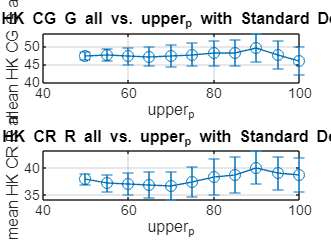

% Definir los valores de upper_p
upper_p_values = 100:-5:50;

% Plotear los resultados
figure;

% Plot para HK_CG_G_all vs. upper_p
subplot(2,1,1);
errorbar(upper_p_values, mean_HK_CG_G_all, std_HK_CG_G_all, 'o-');
xlabel('upper_p');
ylabel('mean HK CG G all');
title('Mean HK CG G all vs. upper_p with Standard Deviation');
grid on;

% Plot para HK_CR_R_all vs. upper_p
subplot(2,1,2);
errorbar(upper_p_values, mean_HK_CR_R_all, std_HK_CR_R_all, 'o-');
xlabel('upper_p');
ylabel('mean HK CR R all');
title('Mean HK CR R all vs. upper_p with Standard Deviation');
grid on;

% Guardar la figura
saveas(gcf, 'results_plot_upper_p.png');